%% Plot takeoff distance vs CLmax from lookup table
% Uses one chosen baseline geometry / condition and evaluates
% takeoff distance for each flap setting in the lookup table.

clear
clc

%% -----------------------------
% Load lookup table
% ------------------------------
baseDir = fileparts(matlab.desktop.editor.getActiveFilename);
lookupPath = fullfile(baseDir, '../+Unconventional/+lookup/+aerodynamics/AVL_lookup_table.mat');

S = load(lookupPath);
lookup_results = S.Results;

%% -----------------------------
% Example baseline values
% ------------------------------
span       = 73.5;    % m
mach       = 0.20;    % representative takeoff Mach
rootChord  = 15.2;    % m
altitude   = 0;       % sea level

MTOM            = 490000;   % kg
Thrust          = 1.45e6*0.8;   % N  <-- example value, replace later
runwayRequired  = 2800;     % m  <-- example runway target

%% -----------------------------
% Snap to nearest available lookup values
% ------------------------------
span      = S.spanVec(nearestIndex(S.spanVec,span));
mach      = S.machVec(nearestIndex(S.machVec,mach));
rootChord = S.rootChordVec(nearestIndex(S.rootChordVec,rootChord));
altitude  = S.altVec(nearestIndex(S.altVec,altitude));

fprintf('Using lookup case:\n');

Using lookup case:


fprintf('  Span      = %.3f m\n', span);

  Span      = 78.000 m


fprintf('  Mach      = %.3f\n', mach);

  Mach      = 0.200


fprintf('  RootChord = %.3f m\n', rootChord);

  RootChord = 17.000 m


fprintf('  Altitude  = %.3f m\n', altitude);

  Altitude  = 0.000 m



%% -----------------------------
% Filter lookup table to chosen baseline
% ------------------------------
iCase = [lookup_results.WingSpan] == span & ...
        [lookup_results.Mach] == mach & ...
        [lookup_results.RootChord] == rootChord & ...
        [lookup_results.Altitude] == altitude;

caseRows = lookup_results(iCase);
assert(~isempty(caseRows), 'No matching rows found in lookup table.')

%% -----------------------------
% Collapse repeated alpha rows
% Keep one row per flap setting
% ------------------------------
allFlap = [caseRows.FlapDeflection]';
[flapUnique, firstIdx] = unique(allFlap, 'stable');
caseRowsUnique = caseRows(firstIdx);

%% -----------------------------
% Preallocate arrays
% ------------------------------
nFlap = numel(caseRowsUnique);

CLmaxVec    = nan(nFlap,1);
STOVec      = nan(nFlap,1);
FlapVec     = nan(nFlap,1);
CDTO_Vec    = nan(nFlap,1);
WingAreaVec = nan(nFlap,1);

%% -----------------------------
% Compute takeoff distance for each flap setting
% ------------------------------
for j = 1:nFlap
    r = caseRowsUnique(j);

    FlapVec(j)     = r.FlapDeflection;
    CLmaxVec(j)    = r.CLmaxFlap;
    WingAreaVec(j) = r.WingArea;

    if ~isnan(r.CD_withFlap)
        CDTO_Vec(j) = r.CD_withFlap;
    elseif ~isnan(r.CD0)
        CDTO_Vec(j) = r.CD0;
    else
        continue
    end

    if isnan(CLmaxVec(j)) || isnan(WingAreaVec(j))
        continue
    end

    ac = struct();
    ac.MTOM         = MTOM;
    ac.WingArea     = r.WingArea;
    ac.Thrust       = Thrust;
    ac.CD0_TO       = CDTO_Vec(j);
    ac.K            = 0.045;

    ac.mu_roll      = 0.02;
    ac.rho          = 1.225;
    ac.g            = 9.81;

    ac.CLmax_TO     = CLmaxVec(j);

    ac.screen_h_TO  = 10.7;
    ac.gamma_climb  = deg2rad(8);
    ac.n_rot        = 1.10;
    ac.n_lof        = 1.20;

    TO = takeoff_distance_case(ac);
    STOVec(j) = TO.STO;
end

%% -----------------------------
% Remove invalid entries
% ------------------------------
idx = ~isnan(FlapVec) & ~isnan(CLmaxVec) & ~isnan(STOVec);

FlapVec     = FlapVec(idx);
CLmaxVec    = CLmaxVec(idx);
STOVec      = STOVec(idx);
CDTO_Vec    = CDTO_Vec(idx);
WingAreaVec = WingAreaVec(idx);

assert(~isempty(FlapVec), 'No valid flap cases available after filtering.')

%% -----------------------------
% Print results table
% ------------------------------
T = table(FlapVec, CLmaxVec, CDTO_Vec, WingAreaVec, STOVec, ...
    'VariableNames', {'FlapDeflection_deg','CLmax_TO','CD0_TO_used','WingArea_m2','TakeoffDistance_m'});
disp(T)

    FlapDeflection_deg    CLmax_TO    CD0_TO_used    WingArea_m2    TakeoffDistance_m
    __________________    ________    ___________    ___________    _________________

             0             1.1533       0.001093         716             3347.2      
             2             1.2322       0.001695         716             3182.2      
             4             1.3109      0.0022502         716             3035.1      
             6             1.3894      0.0028498         716             2892.2      
             8             1.4677      0.0035651         716             2783.7      
            10             1.5458      0.0044496         716             2686.4      
            12             1.6236      0.0055409         716             2609.3      
            14             1.7013      0.0068635       


%% -----------------------------
% Estimate minimum CLmax needed
% ------------------------------
requiredCLmax = NaN;
if numel(CLmaxVec) >= 2
    [STOSort, ord] = sort(STOVec);
    CLmaxSort = CLmaxVec(ord);

    [STOUnique, ia] = unique(STOSort, 'stable');
    CLmaxUnique = CLmaxSort(ia);

    try
        requiredCLmax = interp1(STOUnique, CLmaxUnique, runwayRequired, 'linear', 'extrap');
    catch
        requiredCLmax = NaN;
    end
end

if ~isnan(requiredCLmax)
    fprintf('\nEstimated CLmax needed for %.1f m runway: %.3f\n', runwayRequired, requiredCLmax);
else
    fprintf('\nCould not interpolate a unique required CLmax value.\n');
end


Estimated CLmax needed for 2800.0 m runway: 1.456


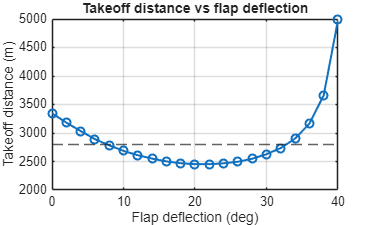


%% -----------------------------
% Plot 1: Takeoff distance vs flap deflection
% ------------------------------
figure
plot(FlapVec, STOVec, '-o', 'LineWidth', 1.5)
hold on
yline(runwayRequired, '--')
xlabel('Flap deflection (deg)')
ylabel('Takeoff distance (m)')
grid on
title('Takeoff distance vs flap deflection')
hold off

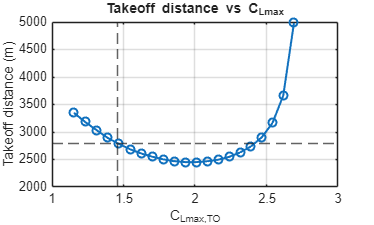


%% -----------------------------
% Plot 2: Takeoff distance vs CLmax
% ------------------------------
figure
plot(CLmaxVec, STOVec, '-o', 'LineWidth', 1.5)
hold on
yline(runwayRequired, '--')
if ~isnan(requiredCLmax)
    xline(requiredCLmax, '--')
end
xlabel('C_{Lmax,TO}')
ylabel('Takeoff distance (m)')
grid on
title('Takeoff distance vs C_{Lmax}')
hold off

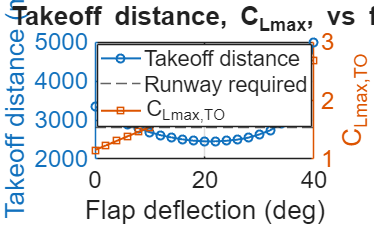


%% -----------------------------
% Plot 3: Additional plot to reveal the trade
% CDTO and CLmax vs flap deflection
% ------------------------------
figure
yyaxis left
plot(FlapVec, STOVec, '-o', 'LineWidth', 1.5)
ylabel('Takeoff distance (m)', 'FontSize', 18)
hold on
yline(runwayRequired, '--')

yyaxis right
plot(FlapVec, CLmaxVec, '-s', 'LineWidth', 1.5)
ylabel('C_{Lmax,TO}', 'FontSize', 18)

xlabel('Flap deflection (deg)', 'FontSize', 18)
grid on
title('Trade plot: Takeoff distance, C_{Lmax}, vs flap deflection', 'FontSize', 22)
legend('Takeoff distance', 'Runway required', 'C_{Lmax,TO}', 'Location', 'best')
set(gca, 'FontSize', 18)
hold off


%% -----------------------------
% Local helper functions
% ------------------------------
function k = nearestIndex(vec,x)
    [~,k] = min(abs(vec-x));
end

function TO = takeoff_distance_case(ac)
% Simple conceptual takeoff model:
% 1) Ground roll from rest to lift-off
% 2) Transition/climb to screen height

    W   = ac.MTOM * ac.g;
    rho = ac.rho;
    S   = ac.WingArea;

    % Characteristic speeds
    Vs_to = sqrt(2*W/(rho*S*ac.CLmax_TO));
    Vr    = ac.n_rot * Vs_to;
    Vlof  = ac.n_lof * Vs_to;

    % Ground roll integration
    dt = 0.1;
    V  = 0.1;
    x  = 0.0;
    t  = 0.0;

    while V < Vlof
        CL = ac.CLmax_TO * min((V/Vlof)^2, 1.0) * 0.7;
        CD = (ac.CD0_TO*7) + ac.K * CL^2;

        q = 0.5 * rho * V^2;
        L = q * S * CL;
        D = q * S * CD;

        N = max(W - L, 0);
        F_fric = ac.mu_roll * N;

        a = (ac.Thrust - D - F_fric) / ac.MTOM;

        if a < 0.05
            a = 0.05;
        end

        V = V + a*dt;
        x = x + V*dt;
        t = t + dt;
    end

    Sg = x;
    tg = t;

    % Airborne distance to screen height
    Sc = ac.screen_h_TO / tan(ac.gamma_climb);

    TO.Vs_to = Vs_to;
    TO.Vr    = Vr;
    TO.Vlof  = Vlof;
    TO.Sg    = Sg;
    TO.Sc    = Sc;
    TO.STO   = Sg + Sc;
    TO.tg    = tg;
end